filename = "ECE113/ece113dw_project/audio_data/eggert/eggert_1.wav";
[word, Fs] = audioread(filename);

Pre-emphasis filter

windowing

% Framing settings
win_sz = 128;
overlap = 64;

% Windowing settings
windowing = true;
a0 = 0.5; %0.5 for hanning window, 0.54 for hamming

num_frames =  size(word, 1)/overlap-1;

win = a0-(1-a0)*cos(2*pi*(1:win_sz)/win_sz);
frames = zeros(num_frames, win_sz);
for i=0:num_frames-1
    frames(i+1,:) = word(i*overlap+1:i*overlap+win_sz,1)';
end

if(windowing)
    frames = frames .* repmat(win, num_frames, 1);
end

FFT

freq_frames = fftshift(fft(frames,win_sz, 2), 2);

Mel filter bank

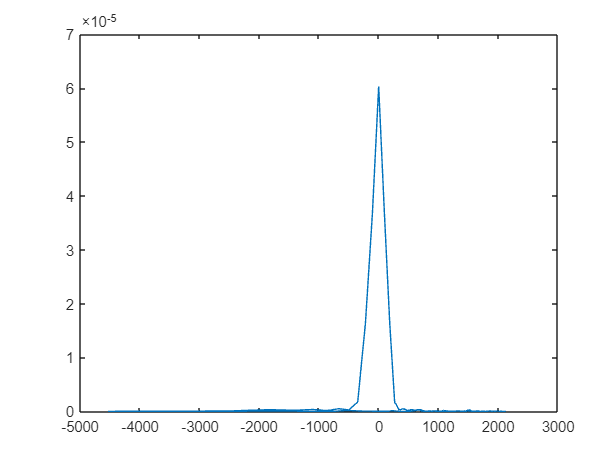

% mel filter settings
num_bands = 32;

% convert FFT to power spectrum
pwr = (abs(freq_frames).^2)./win_sz;
% input is real signal, assign freqs as such
freqs = Fs/win_sz*(-win_sz/2:win_sz/2-1);
% shift frequencies to mel spectrum
mel = 2595*log10(1+freqs/700);

plot(mel, pwr(1,:));